clc; clear;

data = load('data_Devoir_3.mat');


## 1. Étude du modèle en boucle ouverte

## a


% Symbolic variables
syms m g0 R L kf he

% Numerical values
m_val  = 0.025;        % kg
g0_val = 9.81;         % m/s^2
R_val  = 22.5;         % Ohm
L_val  = 0.084;        % H
kf_val = 2.725e-4;     % N*m^2/A^2
he_val = -0.05;        % m

sym_vars = [m, g0, R, L, kf, he];
val_vars = [m_val, g0_val, R_val, L_val, kf_val, he_val];

syms h dh i u

Fm = kf * (i/h)^2;
Fg = m*g0;

ddh = (Fm-Fg)/m;
di = (u-R*i)/L;

x_phys = [ h dh i];
f_phys = [dh ddh di];
y_phys = h;


## b



syms x1 x2 x3

x_etat = [x1 x2 x3];

f_etat = subs(f_phys,x_phys,x_etat);
y_etat = subs(y_phys,x_phys,x_etat);

eq1 = subs(f_etat(1),x1,he)==0;
eq2 = subs(f_etat(2),x1,he)==0;

sol = solve([eq1 eq2], [x2 x3]);


sol.x2;
sol.x3;

x_equi_sym = [he sol.x2(1,1) sol.x3(1,1)]

$$x\_equi\_sym = \left(\begin{array}{ccc} \mathrm{he} & 0 & \mathrm{he}\,\sqrt{\frac{g_{0}\,m}{\mathrm{kf}}} \end{array}\right)$$

x_equi_val = subs(x_equi_sym, sym_vars,val_vars)

$$x\_equi\_val = \left(\begin{array}{ccc} -\frac{1}{20} & 0 & -\frac{\sqrt{69815802223414625}\,\sqrt{62834222001073160192}}{1396316044468292500} \end{array}\right)$$

vpa(x_equi_val,3)

$$ans = \left(\begin{array}{ccc} -0.05 & 0 & -1.5 \end{array}\right)$$

## c


% Define the state-space representation
A_sym = jacobian(f_etat, x_etat);
B_sym = jacobian(f_etat, u);
C_sym = jacobian(y_etat, x_etat);
D_sym = jacobian(y_etat, u);

A_val = subs(A_sym, [x_etat sym_vars], [x_equi_val val_vars]);
B_val = subs(B_sym, [x_etat sym_vars], [x_equi_val val_vars]);
C_val = subs(C_sym, [x_etat sym_vars], [x_equi_val val_vars]);
D_val = subs(D_sym, [x_etat sym_vars], [x_equi_val val_vars]);

A_val_round = vpa(A_val,3);
B_val_round = vpa(B_val,3);
C_val_round = vpa(C_val,3);
D_val_round = vpa(D_val,3);


## d

% s = tf('s');

syms s;

I = eye(size(A_sym));

G_sym = subs(C_sym*inv(s*I - A_sym)*B_sym + D_sym, x_etat,x_equi_sym)

$$G\_sym = \frac{2\,{\mathrm{he}}^{2}\,\mathrm{kf}\,\sqrt{\frac{g_{0}\,m}{\mathrm{kf}}}}{\left(m\,{\mathrm{he}}^{3}\,s^{2}+2\,g_{0}\,m\,{\mathrm{he}}^{2}\right)\,\left(R+L\,s\right)}$$

[num, den] = numden(G_sym);   % separate numerator & denominator
poles = solve(den == 0, s) 

$$poles = \left(\begin{array}{c} -\frac{R}{L}\\ \frac{\sqrt{2}\,\sqrt{-g_{0}}}{\sqrt{\mathrm{he}}}\\ -\frac{\sqrt{2}\,\sqrt{-g_{0}}}{\sqrt{\mathrm{he}}} \end{array}\right)$$

## e

G_val = collect(subs(G_sym, sym_vars, val_vars));
G_val_vpa = vpa(G_val,3)

$$G\_val\_vpa = \frac{7.85e+20}{-5.04e+18\,s^{3}-1.35e+21\,s^{2}+1.98e+21\,s+5.3e+23}$$

poles_val = subs(poles, sym_vars, val_vars);
poles_val_vpa = vpa(poles_val,3)

$$poles\_val\_vpa = \left(\begin{array}{c} -268.0\\ 19.8\\ -19.8 \end{array}\right)$$

## f

%% -268 est neglieable car || du pole >> || des autres

## g



[num_full, den_full] = numden(G_val);
num_full = double(sym2poly(num_full));
den_full = double(sym2poly(den_full));

K = num_full(end) / den_full(end); 

poles = double([poles_val(2) poles_val(3)]);
den = poly(poles);

Ga = tf(K, den)


Ga =
 
   0.001481
  -----------
  s^2 - 392.4
 
Continuous-time transfer function.


## 2

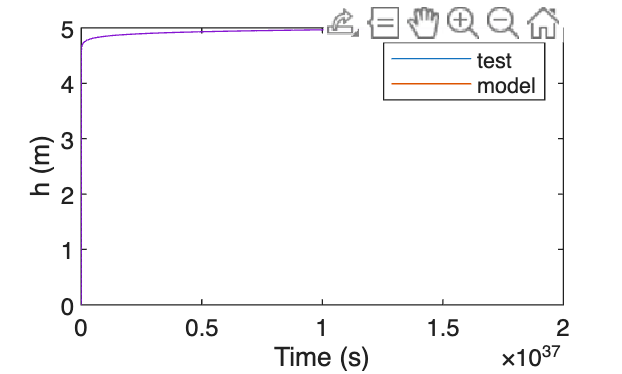

Kp = 1;
Kd = 1;

timeOfSimulation = 5;
dt = 0.01;

t = (0:dt:timeOfSimulation)';
u = ones(size(t));

simin = [t u];

set_param('Sim_02','Solver','ode4');
set_param('Sim_02','FixedStep',num2str(dt));
out = sim('Sim_02','StopTime',num2str(timeOfSimulation));

y = out.h.data;
time = out.h.time;

plot(data.y,data.t)
hold on
plot(y,time)
xlabel('Time (s)')
ylabel('h (m)')
legend(["test" "model"])